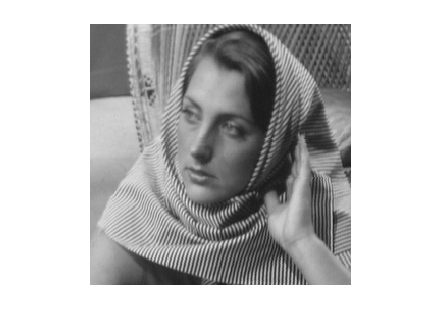

I = double(imread("barbara256.png"));
imshow(I/255);

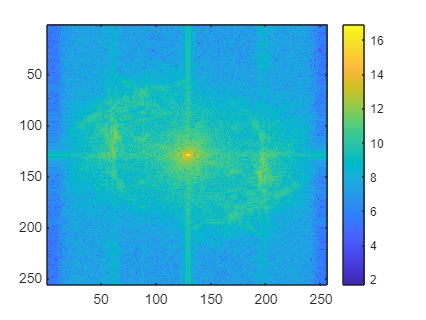

J = fftshift(fft2(I));
imagesc(log(abs(J))+1);
colorbar;

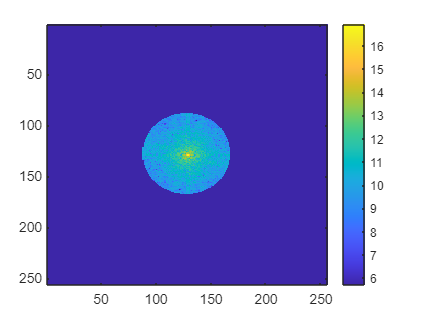

J1 = J;
J2 = J;

for i=1:256
    for j=1:256
        if (i-(127.5))^2 + (j-(127.5))^2 > 1600
            J1(i,j) = 0;
            J2(i,j) = 0;
        elseif (i-(127.5))^2 + (j-(127.5))^2 > 6400
            J2(i,j) = 0;
        end
    end
end
imagesc(log(abs(J1))+1);
colorbar;

imagesc(log(abs(J2))+1);
colorbar;

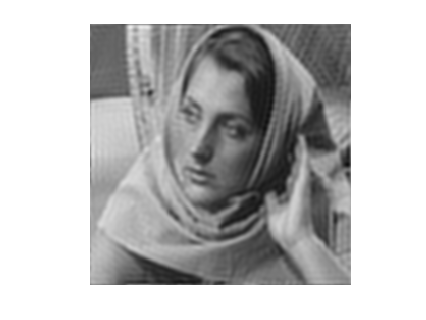

I_ideal_40 = abs(ifft2(J1));
I_ideal_80 = abs(ifft2(J2));

imshow(I_ideal_40/255);

imshow(I_ideal_80/255);

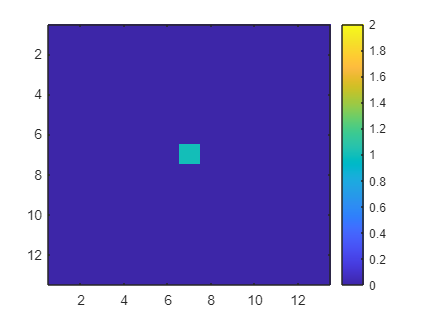


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       Manually creating a kxk Gaussian Low pass filter kernel
k = 13;
GLP1 = double(zeros(k,k));
GLP2 = double(zeros(k,k));
for i=1:k
    for j=1:k
        GLP1(i,j) = exp(-(((i-((k+1)/2.00))^2+(j-((k+1)/2.00))^2)*1600.00)/2.00);
        GLP2(i,j) = exp(-(((i-((k+1)/2.00))^2+(j-((k+1)/2.00))^2)*6400.00)/2.00);
    end
end
imagesc(log(abs(GLP1))+1);
colorbar;

imagesc(log(abs(GLP2))+1);
colorbar;

I_padded = padarray(I, [(k-1)/2, (k-1)/2], "both");
I_Gauss_40 = double(zeros(size(I)));
I_Gauss_80 = double(zeros(size(I)));
for i=1:256
    for j=1:256
        temp = I_padded(i:i+k-1, j:j+k-1);
        temp1 = temp.*GLP1;
        temp2 = temp.*GLP2;
        temp1 = sum(temp1, "all");
        temp2 = sum(temp2, "all");
        I_Gauss_40(i,j) = temp1;
        I_Gauss_80(i,j) = temp2;
    end
end
imshow(I_Gauss_40/255);

imshow(I_Gauss_80/255);